clc,clear,close all
n = 1e7;

d = (1:n)';
e = ones(n,1);
A = spdiags([e/2 e/2 d e/2 e/2],-2:2,n,n);


b = A*ones(n,1);

disp('条件数为')

条件数为


% disp(condest(A))

rng(10)

tol = 1e-10;
max_iter = 13;
x0 = rand(n,1);

tic
% [~,iter0,err1] = jacobi(A,b,x0, tol, max_iter);
toc

历时 0.000981 秒。



% 
% tic
% [~,iter2,err2] = gauss_seidel(A,b,x0, tol, max_iter);
% toc
% 
% tic
% [~,iter3,err3] = sor(A,b,1.05,x0, tol, max_iter);
% toc
% 
% % plot(1:length(err1),log(err1)/log(10),'-o',  1:length(err2),log(err2)/log(10),'-o',  1:length(err3),log(err3)/log(10),'-o',  LineWidth=2)
% loglog(1:length(err1),err1,'-o',  1:length(e6rr2),err2,'-o',  1:length(err3),err3,'-o',  LineWidth=2)
% 
% legend('Jacobi','Gauss Seidel', 'SOR')
% xlabel('迭代次数')
% ylabel('方程误差')

tic
% [~,iter4,err4] = preconditioned_conjugate_gradient(A, b, speye(n), x0, tol, max_iter);
toc

历时 0.000709 秒。



tic
[x,iter5,err5] = preconditioned_conjugate_gradient(A, b, spdiags(diag(A), 0, n, n), x0, tol, max_iter);

toc

历时 16.740319 秒。


iter5

iter5 = 13

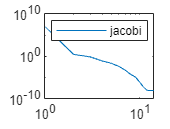


loglog(err5)
% loglog(1:length(err1),err1,'-o',  1:length(err4),err4,'-o', 1:length(err5),err5,'-o',  LineWidth=2)
legend('jacobi','共轭梯度法','预条件子共轭梯度法')